# AuE-6600 | Dynamic Performance of Vehicles

## Homework 1

### Problem 1

In 1955 Rudolf Uhlenhaut, the Mercedes Motorsport Chief at the time, created one of the most unique cars of all time. Having been responsible for a famous series of race cars, the ‘silver arrow’ as well as the 300 SLR racing car, he built two prototype race cars by combining feature from the iconic 300SL Gullwing and the SLR into a closed coupe. As Mercedes withdrew from competitive motorsport at the end of 1955 (due to an accident), the car never made it to the racetrack. It became Uhlenhaut’s personal company car from that moment on and easily earned the title of being the era’s fastest street legal car.

[https://en.wikipedia.org/wiki/Mercedes-Benz_300_SLR](https://en.wikipedia.org/wiki/Mercedes-Benz_300_SLR)

It really was a race car in disguise and its lack of any significant exhaust muffling made it a great nuisance to Uhlenhaut’s neighbors as they were chased out of bed early morning on a regular basis when Uhlenhaut went to work. Uhlenhaut never owned a car of his own and needed hearing aids in the latter half of his life, possibly due to his loud cars. Auctioneers estimate the value of the Uhlenhaut Coupe (which is not for sale) to be around 60-70 million dollars.

Data on the Uhlenhaut Coupe is rare, but Mercedes and later independent testing published the following data: top speed 290 kph, 2982 cc Inline 8 twin-spark engine producing 310 hp with dry sump. The car’s weight was 1117 kg, wheelbase 2370 mm, front track 1330 mm, rear track 1380 mm, length 4350 mm, width 1750 mm, and height 1210 mm.

- Calculate the aerodynamic drag force acting on the Uhlenhaut Coupe at terminal velocity assuming 230 hp at wheels.

- Determine CDA (now assume 12.5 % drivetrain loss). Estimate CD by approximating A with car dimensions and approximation formula from lecture notes.

- The Koenigsegg Agera RS is the world’s fastest street legal production car, achieving a terminal velocity of 278 mph in November 2017. Koenigsegg claims the engine produces 1160 hp at the wheels. Assuming a frontal area of 20.16 ft2 and standard atmospheric density, what is the Agera’s drag coefficient?

- How many hp at the wheels would the Mercedes need to go as fast as the Agera (Assume CDA is unaffected by the modification needed to achieve this extra horsepower)?

### Solution 1

1. Calculate the aerodynamic drag force acting on the Uhlenhaut Coupe at terminal velocity assuming 230 hp at wheels.

P_w = 230; % hp
P_w = P_w * 745.699872; % watt
V = 290; % km/h
V = V/3.6; % m/s

F_D = P_w/V; % N
fprintf('Aerodynamic drag force acting on the Uhlenhaut Coupe is %.4f N', F_D);

Aerodynamic drag force acting on the Uhlenhaut Coupe is 2129.1017 N

2. Determine CDA (now assume 12.5 % drivetrain loss). Estimate CD by approximating A with car dimensions and approximation formula from lecture notes.

P_e = 310; % hp
P_e = P_e * 745.699872; % watt
P_w = ((100-12.5)/100) * P_e; % watt
rho = 1.225; % kg/m^3 @ 15 °C, 101.32 kPa
V = 290; % km/h
V = V/3.6; % m/s

CD_Af = (2*P_w)/(rho*V^3); % m^2
fprintf('CDA of the Uhlenhaut Coupe is %.4f m^2', CD_Af);

CDA of the Uhlenhaut Coupe is 0.6317 m^2

w = 1750; % mm
w = w/1000; % m
h = 1210; % mm
h = h/1000; % m
A_f = 0.815 * w * h; % m^2

C_D = CD_Af/A_f; % unitless
fprintf('Drag coefficient of the Uhlenhaut Coupe is %.4f', C_D);

Drag coefficient of the Uhlenhaut Coupe is 0.3661

3. The Koenigsegg Agera RS is the world’s fastest street legal production car, achieving a terminal velocity of 278 mph in November 2017. Koenigsegg claims the engine produces 1160 hp at the wheels. Assuming a frontal area of 20.16 ft2 and standard atmospheric density, what is the Agera’s drag coefficient?

P_w = 1160; % hp
P_w = P_w * 745.699872; % watt
V = 278; % mph
V = V * 0.44704; % m/s
A_f = 20.16; % ft^2
A_f = A_f * 0.09290304; % m^2
rho = 1.225; % kg/m^3 @ 15 °C, 101.32 kPa

C_D = (2*P_w)/(rho*V^3*A_f); % unitless
fprintf('Drag coefficient of Agera RS is %.4f', C_D);

Drag coefficient of Agera RS is 0.3928

4. How many hp at the wheels would the Mercedes need to go as fast as the Agera (Assume CDA is unaffected by the modification needed to achieve this extra horsepower)?

P_w_K = 1160; % hp
P_w_K = P_w_K * 745.699872; % watt
V_K = 278; % mph
V_K = V_K * 0.44704; % m/s
C_D_K = 0.3928;
A_f_K = 20.16; % ft^2
A_f_K = A_f_K * 0.09290304; % m^2

V_M = V_K; % m/s
w_M = 1750; % mm
w_M = w_M/1000; % m
h_M = 1210; % mm
h_M = h_M/1000; % m
C_D_M = 0.3661;
A_f_M = 0.815 * w_M * h_M; % m^2

rho = 1.225; % kg/m^3 @ 15 °C, 101.32 kPa

F_D_K = 0.5 * rho * V_K^2 * C_D_K * A_f_K; % N
F_D_M = 0.5 * rho * V_M^2 * C_D_M * A_f_M; % N

P_w_M = P_w_K - (V_K*F_D_K) + (V_M*F_D_M); % watt
P_w_M = P_w_M/745.699872; % hp
fprintf('Mercedes Uhlenhaut Coupe needs %.4f HP to go as fast as Koenigsegg Agera RS', P_w_M);

Mercedes Uhlenhaut Coupe needs 996.2197 HP to go as fast as Koenigsegg Agera RS

### Problem 2

Assume a racecar has acceleration limits as shown in the g-g diagram below. For simplicity, the maximum driving acceleration is assumed to be constant - a power-limited value estimated for the expected velocity range. Cornering and braking limits are also assumed to be velocity independent.

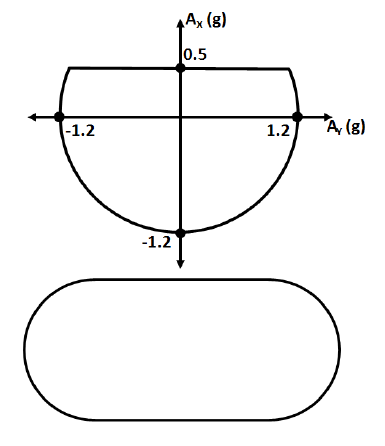

Determine the minimum time solution for this car to complete a lap of the track below. Solve for a “flying lap” - the car does not start from zero velocity. Each of the two straightaways are 0.4 miles

long, and each 180 deg. Corner is also 0.35 miles long. Thus, one lap is 1.5 miles in length. Assume counterclockwise direction (left turns).

To simplify the calculations, assume the car accelerates in only one direction at a time - thus holding constant speed while cornering. Assume the transitions between the straightaways and the corners (a change in radius) happen instantaneously. Assume that the corners have a constant radius.

In the end, report the following (note that these quantities are not necessarily computed in this order):

- Minimum time required for one lap

- Average speed for one lap

- The cornering speed

- The maximum speed achieved on the straights

- The location of the braking transition point (measured as a distance from the previous corner)

### Solution 2

3. The cornering speed

R = 0.35/pi; % miles
R = R * 1609.344; % m
a_y = 1.2; % g
a_y = a_y * 9.80665; % m/s^2

V_cor = abs(sqrt(R*a_y)); % m/s
fprintf('The cornering speed is %.4f m/s', V_cor);

The cornering speed is 45.9340 m/s

5. The location of the braking transition point (measured as a distance from the previous corner)

V_i_a = V_cor; % m/s
V_i_b = V_cor; % m/s
a_x_a = 0.5; % g
a_x_a = a_x_a * 9.80665; % m/s^2
a_x_b = -1.2; % g
a_x_b = a_x_b * 9.80665; % m/s^2
L = 0.4; % miles
L = L * 1609.344; % m

S_T = (V_i_b^2 - V_i_a^2 + (2*abs(a_x_b)*L)) / (2 * (a_x_a + abs(a_x_b)));
fprintf('The location of braking transition point is %.4f m', S_T);

The location of braking transition point is 454.4030 m

4. The maximum speed achieved on the straights

V_max = abs(sqrt(V_i_a^2 + (2 * a_x_a * S_T)));
fprintf('The maximum speed achieved on straights is %.4f m/s', V_max);

The maximum speed achieved on straights is 81.0315 m/s

2. Average speed for one lap

V_avg = (V_max + 2*V_cor)/3; % m/s
fprintf('The average speed for one lap is %.4f m/s', V_avg);

The average speed for one lap is 57.6332 m/s

1. Minimum time required for one lap

Dist = 1.5; % miles
Dist = Dist * 1609.344; % m
t_min = Dist/V_avg; % s
fprintf('The minimum time required for one lap is %.4f s', t_min);

The minimum time required for one lap is 41.8859 s

### Problem 3

Repeat the scenario above, but this time include a variable maximum driving acceleration based on 370 hp available at the wheels. This car has a drag area of CDA = 7.5 ft2 and has a mass of 80 slugs. Assume braking and cornering accelerations remain constant.

As before, report the following:

- Minimum time required for one lap

- Average speed for one lap

- The cornering speed

- The maximum speed achieved on the straights

- The location of the braking transition point (measured as a distance from the previous corner)

### Solution 3

3. The cornering speed

R = 0.35/pi; % miles
R = R * 1609.344; % m
a_y = 1.2; % g
a_y = a_y * 9.80665; % m/s^2

V_cor = abs(sqrt(R*a_y)); % m/s
fprintf('The cornering speed is %.4f m/s', V_cor);

The cornering speed is 45.9340 m/s

5. The location of the braking transition point (measured as a distance from the previous corner)

P_w = 370; % hp
P_w = P_w * 745.699872; % watt
CD_Af = 7.5; % ft^2
CD_Af = CD_Af * 0.09290304; % m^2
m = 80; % slugs
m = m * 14.5939; % kg
rho = 1.225; % kg/m^3 @ 15 °C, 101.32 kPa
L = 0.4; % miles
L = L * 1609.344; % m
a_x_b = -1.2; % g
a_x_b = a_x_b * 9.80665; % m/s^2

a_x = []; % m/s^2
V = []; % m/s
S = []; % m
V(1) = V_cor;
S(1) = 0;
dt = 0.001; % s
t = 1; % discrete time instant

while S(t) < L
    a_x(t) = (P_w-(0.5*rho*V(t)^3*CD_Af))/(m*V(t));
    V(t+1) = V(t) + a_x(t)*dt;
    S(t+1) = S(t) + V(t)*dt;
    t = t+1;
    if abs(V(t)^2 - (V_cor^2 + 2*abs(a_x_b)*(L-S(t)))) <= 1 % tolerance to numerically find intersection point
        break;
    end
end
S_T = S(end);
fprintf('The location of braking transition point is %.4f m', S_T);

The location of braking transition point is 527.1070 m

4. The maximum speed achieved on the straights

V_max = V(end);
fprintf('The maximum speed achieved on straights is %.4f m/s', V_max);

The maximum speed achieved on straights is 69.6719 m/s

2. Average speed for one lap

V_avg = (mean(V) + (V_max+V_cor)/2 + V_cor) / 3; % m/s
fprintf('The average speed for one lap is %.4f m/s', V_avg);

The average speed for one lap is 54.4890 m/s

1. Minimum time required for one lap

Dist = 1.5; % miles
Dist = Dist * 1609.344; % m
t_min = Dist/V_avg; % s
fprintf('The minimum time required for one lap is %.4f s', t_min);

The minimum time required for one lap is 44.3028 s

### Problem 4

Vehicle data collected from a small front wheel drive vehicle for a coast-down procedure is provided in a file named "`LargeFWD1.mat`". The file contains speed of the vehicle and time. The data is collected for a headwind of 4.8 mph

In MATLAB, use the command `load('LargeFWD1.mat')` to introduce variables into the workspace.

Symbols and units used in the file are

- Vx = Speed of the vehicle, m/s

- t    = time, sec

The coast-down procedure is initiated from an initial velocity of 100 kph and ends when the vehicle comes to the stop. Based on the formula given in the lecture notes,


$$\frac{V_t}{V_0} = \frac{1}{\beta} \texttt{tan}(\left [ 1 - \frac{t}{T} \texttt{tan}^{-1} \beta \right ])$$


1. Plot the non-dimensional velocity vs non-dimensional time for values of $\beta$ listed here [1, 1.4, 1.8, 2.2, 2.6, and 3.0].

2. Find the value of $\beta$ which fits the given data.

3. Upon finding the value of $\beta$, calculate the following

        a. Coefficient of drag

        b. Rolling resistance

The vehicle parameters are listed here:

- Mass of the vehicle = 78.8 slugs

- Distance from center of gravity to front axle = 1064 mm

- Wheelbase = 2.66 m

- Frontal area = 22.17 sq. ft

- Use standard density

### Solution 4

load('LargeFWD1.mat')

1. Plot the non-dimensional velocity vs non-dimensional time for values of $\beta$ listed here [1, 1.4, 1.8, 2.2, 2.6, and 3.0]

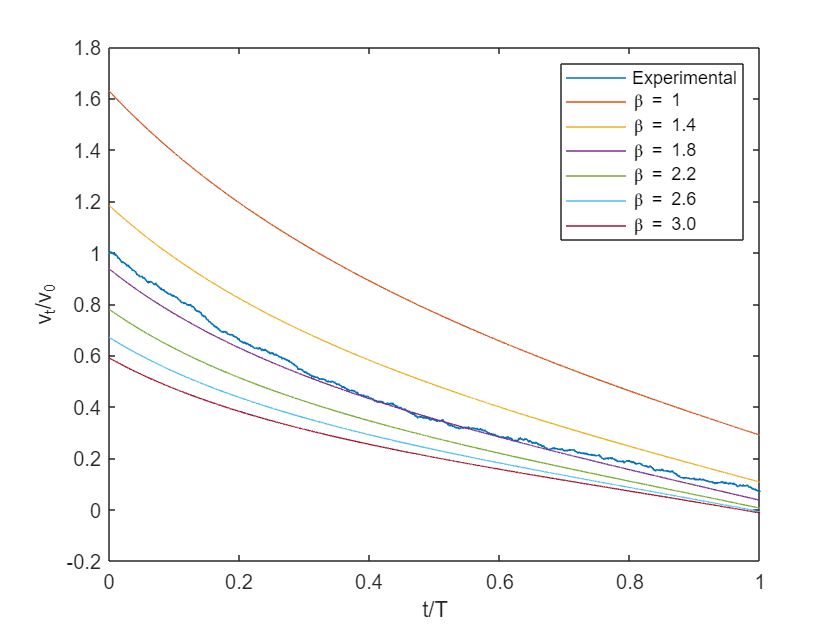

V_wind = 4.8; % mph
V_wind = V_wind * 0.44704; % m/s
T = t(end); % s
V_0 = Vx(1)+V_wind; % m/s

t_by_T = zeros(1, length(t));
Vt_by_V0 = zeros(1, length(Vx));
beta = [1, 1.4, 1.8, 2.2, 2.6, 3.0];

% Plot experimental values
for i = 1:length(t)
    t_by_T(i) = t(i)/T;
    Vt_by_V0(i) = (Vx(i)+V_wind)/V_0;
end
figure(1)
plot(t_by_T, Vt_by_V0);
xlabel('t/T'); ylabel('v_t/v_0');
hold on;
% Plot theoretical values
for j = 1:length(beta)
    for i = 1:length(t)
        t_by_T(i) = t(i)/T;
        V_t = ((V_0/beta(j)) * tan(1-(t(i)/T)*atan(beta(j)))) + V_wind;
        Vt_by_V0(i) = V_t/V_0;
    end
figure(1)
plot(t_by_T, Vt_by_V0);
xlabel('t/T'); ylabel('v_t/v_0');
hold on;
end
legend('Experimental','\beta = 1','\beta = 1.4','\beta = 1.8','\beta = 2.2','\beta = 2.6','\beta = 3.0');

2. Find the value of $\beta$ which fits the given data.

Since the theoretical data corresponding to $\beta$ = 1.8 appears to match the experimental data closest of all, we choose that particular value.

Beta = 1.8;

3. Calculate the drag coefficient and rolling resistance

m = 78.8; % slugs
m = m * 14.5939; % kg
A_f = 22.17; % ft^2
A_f = A_f * 0.09290304; % m^2
rho = 1.225; % kg/m^3 @ 15 °C, 101.32 kPa

3(a). Calculate the drag coefficient

C_D = (2*m*Beta*atan(Beta))/((V_0+V_wind)*T*rho*A_f);
fprintf('Drag coefficient is %.4f', C_D);

Drag coefficient is 0.4446

3(b). Calculate the rolling resistance

R_x = ((V_0+V_wind)*m*atan(Beta))/(Beta*T);
fprintf('Rolling resistance is %.4f N', R_x);

Rolling resistance is 178.3358 N